Te = 0.3;
K = 1;
t=[0:1:30];
Gd = tf(K, [1 1 0]);
G0 = feedback(Gd, 1)


G0 =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.


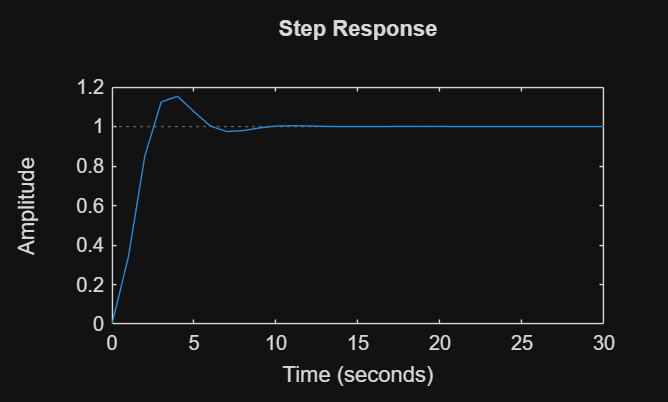

step(G0, t)

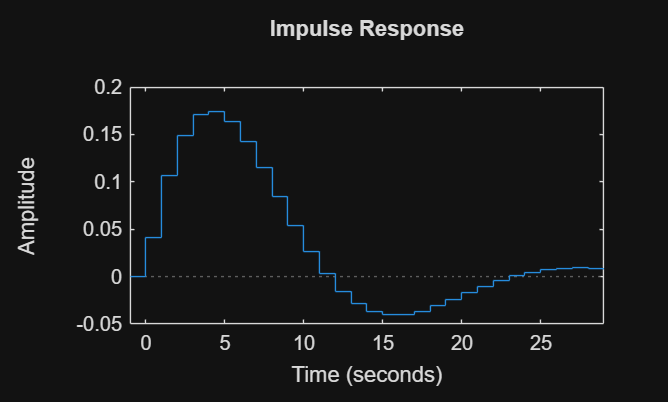

[numd, dend] = c2dm(K, [1 1 0], Te, 'zoh');
[num, den] = feedback(numd, dend, 1, 1);

dimpulse(num, den, t)

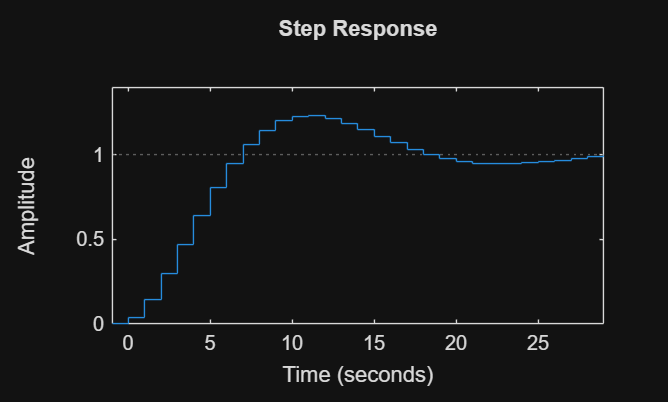

dstep(num, den, t)

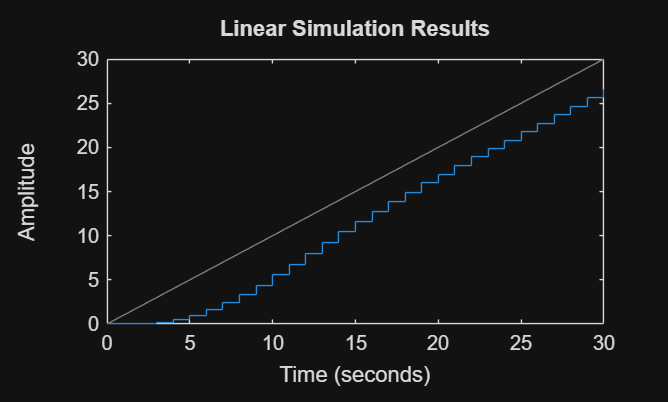

dlsim(num, den, t)

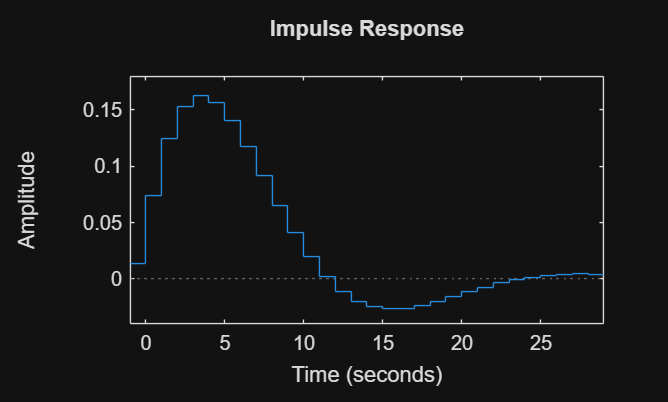

[numd, dend] = c2dm(K, [1 1 0], Te, 'foh');
[num, den] = feedback(numd, dend, 1, 1);

dimpulse(num, den, t)

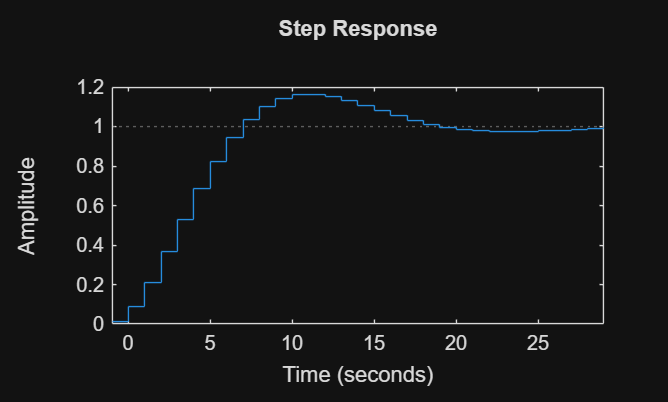

dstep(num, den, t)

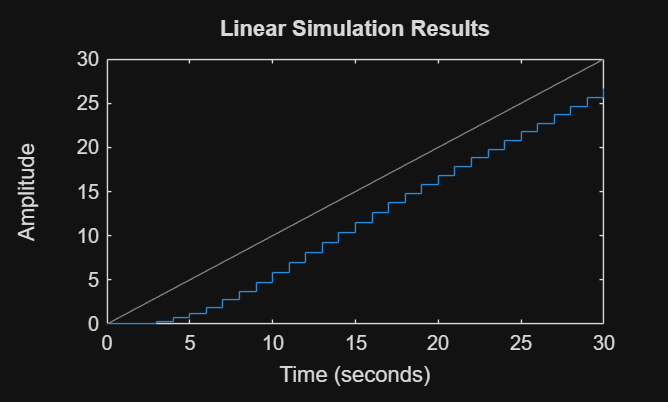

dlsim(num, den, t)

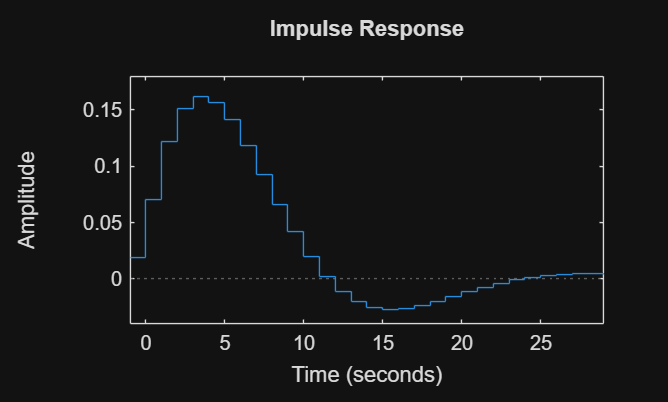

[numd, dend] = c2dm(K, [1 1 0], Te, 'tustin');
[num, den] = feedback(numd, dend, 1, 1);

dimpulse(num, den, t)

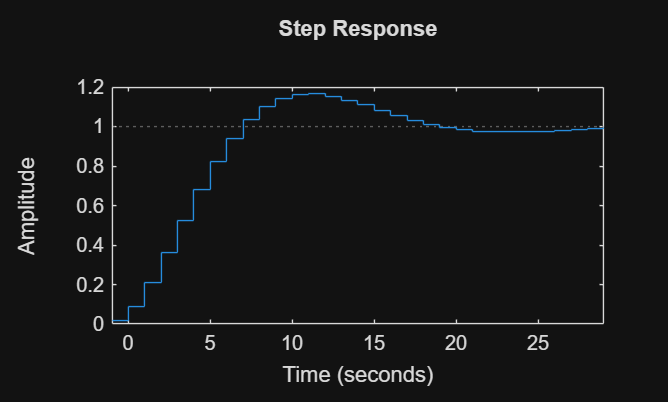

dstep(num, den, t)

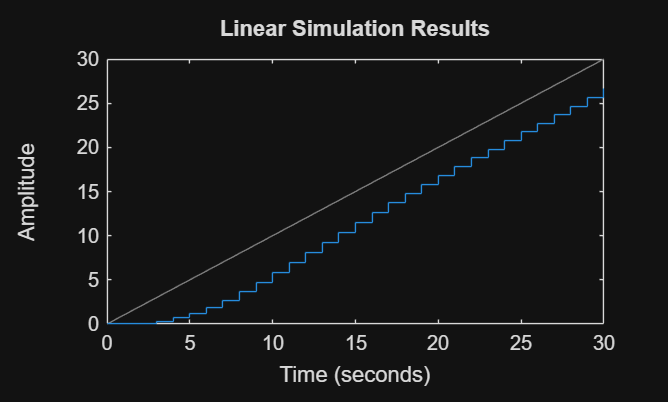

dlsim(num, den, t)

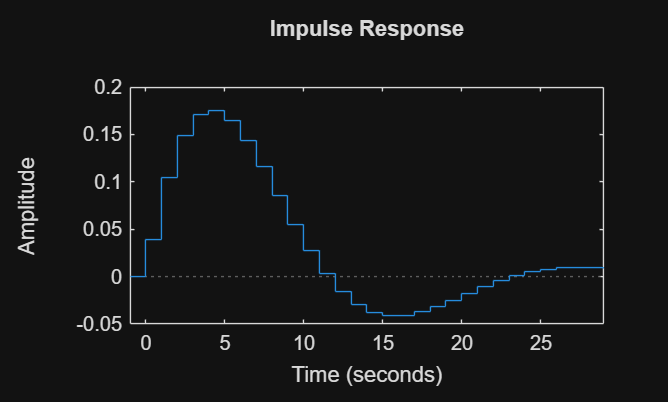

[numd, dend] = c2dm(K, [1 1 0], Te, 'matched');
[num, den] = feedback(numd, dend, 1, 1);

dimpulse(num, den, t)

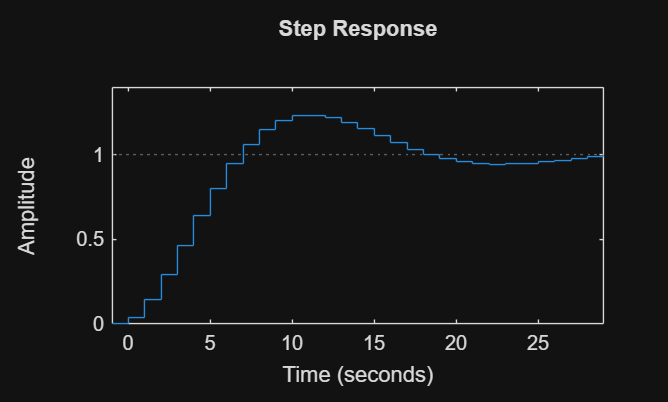

dstep(num, den, t)

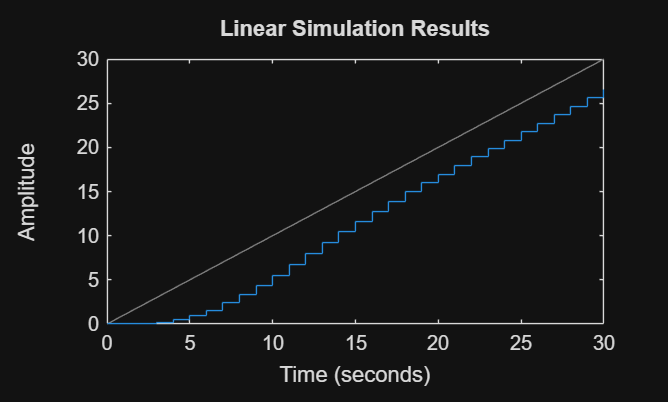

dlsim(num, den, t)